## Example #1

### random 2D point cloud

N = 28;
V = 2*(rand(N,2)-0.5);
G = mean(V,1);
V = V - G;
theta = atan2(V(:,2),V(:,1));
[~,i] = sort(theta);
V = V(i,:);
P = 2*(rand(1e3,2)-0.5);

figure
line([V(:,1); V(1,1)],[V(:,2); V(1,2)],'Color',[0 0 1],'LineWidth',2), hold on;
set(gcf,'Color',[0 0 0]), set(gca,'Color',[0 0 0],'XColor',[1 1 1],'YColor',[1 1 1],'FontSize',16);
xlabel('X'), ylabel('Y');

isinpolygon(V,V(randi(N,1,1),:)) % boundary point test

ans = logical
   1


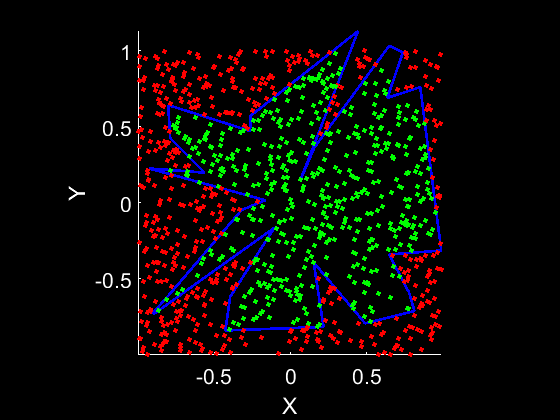

isin = double(isinpolygon(V,P));
ColorSpec = cell2mat(cellfun(@(c) cat(2,~c,c,0),num2cell(isin,2),'un',0));
cellfun(@(r1,r2) plot(r1(1,1),r1(1,2),'s','Color',r2,'MarkerSize',2,'LineWidth',2),num2cell(P,2),num2cell(ColorSpec,2),'un',0);
axis equal, axis tight;